clc
clear all
format long


%%%%%%Variable declaration%%%%%%%%%%%%
%-------------------------------------------%
F_f=0.8 %non-dimensional forcing frequency

F_f =    0.800000000000000


A_mat=0:0.01:1 % non-dimensional forcing amplitude

A_mat =                    0   0.010000000000000   0.020000000000000   0.030000000000000   0.040000000000000   0.050000000000000   0.060000000000000   0.070000000000000   0.080000000000000   0.090000000000000   0.100000000000000   0.110000000000000   0.120000000000000   0.130000000000000   0.140000000000000   0.150000000000000   0.160000000000000   0.170000000000000   0.180000000000000   0.190000000000000   0.200000000000000   0.210000000000000   0.220000000000000   0.230000000000000   0.240000000000000   0.250000000000000   0.260000000000000   0.270000000000000   0.280000000000000   0.290000000000000   0.300000000000000   0.310000000000000   0.320000000000000   0.330000000000000   0.340000000000000   0.350000000000000   0.360000000000000   0.370000000000000   0.380000000000000   0.390000000000000   0.400000000000000   0.410000000000000   0.420000000000000   0.430000000000000   0.440000000000000   0.450000000000000   0.460000000000000   0.470000000000000   0.480000000000000   0.4900000

omega=2*pi*F_f %circular frequency

omega =    5.026548245743669


phi=0; %initial phase
t1=0; % initial time
t_run=40; %final time


dt=1e-5; %time step
num_vor=300; %number of vortices shed;

for A = A_mat
    for j=1:num_vor
        
        tm=(t1):dt:(t1+t_run);
        for i=1:length(tm)
            tt=tm(i+1)-t1; 
            gam(i)=tt*(A^2/4+1/2)-A^2*(sin(2*omega*tm(i+1)+2*phi)-sin(2*omega*t1+2*phi))/(8*omega)+...
                A*(cos(omega*t1+phi)-cos(omega*tm(i+1)+phi))/omega; %Gamma_m
            gam_c(i)=0.5*(1+A*sin(omega*tm(i+1)+phi)); %threshold circulation Gamma_sep
            
            if gam(i)>=gam_c(i)
                gam(i+1)=0;
                tf(j)=tt; %Shedding time period
                break
            end
        end
        
        clear gam gam_c
        t1=tm(i+1);  %t1=t2 condition 
        j;
    end
    p = A*ones(1, length(tf(50:end)));
    A
    %if (omega/(2*pi)) == tf(end)
     %   plot(p(end), 1./tf(end),"ro",'MarkerSize',4)
      %  disp("ha")
    %else
    %plot(p, 1./tf(50:end), "color",'#A2142F',"LineWidth",3, "Marker",".", "MarkerSize", 17)
    plot(p, tf(50:end), "k.","MarkerSize",15)
    %end
    hold on
    clear p
end

A =      0


A =    0.010000000000000


A =    0.020000000000000


A =    0.030000000000000


A =    0.040000000000000


A =    0.050000000000000


A =    0.060000000000000


A =    0.070000000000000


A =    0.080000000000000


A =    0.090000000000000


A =    0.100000000000000


A =    0.110000000000000


A =    0.120000000000000


A =    0.130000000000000


A =    0.140000000000000


A =    0.150000000000000


A =    0.160000000000000


A =    0.170000000000000


A =    0.180000000000000


A =    0.190000000000000


A =    0.200000000000000


A =    0.210000000000000


A =    0.220000000000000


A =    0.230000000000000


A =    0.240000000000000


A =    0.250000000000000


A =    0.260000000000000


A =    0.270000000000000


A =    0.280000000000000


A =    0.290000000000000


A =    0.300000000000000


A =    0.310000000000000


A =    0.320000000000000


A =    0.330000000000000


A =    0.340000000000000


A =    0.350000000000000


A =    0.360000000000000


A =    0.370000000000000


A =    0.380000000000000


A =    0.390000000000000


A =    0.400000000000000


A =    0.410000000000000


A =    0.420000000000000


A =    0.430000000000000


A =    0.440000000000000


A =    0.450000000000000


A =    0.460000000000000


A =    0.470000000000000


A =    0.480000000000000


A =    0.490000000000000


A =    0.500000000000000


A =    0.510000000000000


A =    0.520000000000000


A =    0.530000000000000


A =    0.540000000000000


A =    0.550000000000000


A =    0.560000000000000


A =    0.570000000000000


A =    0.580000000000000


A =    0.590000000000000


A =    0.600000000000000


A =    0.610000000000000


A =    0.620000000000000


A =    0.630000000000000


A =    0.640000000000000


A =    0.650000000000000


A =    0.660000000000000


A =    0.670000000000000


A =    0.680000000000000


A =    0.690000000000000


A =    0.700000000000000


A =    0.710000000000000


A =    0.720000000000000


A =    0.730000000000000


A =    0.740000000000000


A =    0.750000000000000


A =    0.760000000000000


A =    0.770000000000000


A =    0.780000000000000


A =    0.790000000000000


A =    0.800000000000000


A =    0.810000000000000


A =    0.820000000000000


A =    0.830000000000000


A =    0.840000000000000


A =    0.850000000000000


A =    0.860000000000000


A =    0.870000000000000


A =    0.880000000000000


A =    0.890000000000000


A =    0.900000000000000


A =    0.910000000000000


A =    0.920000000000000


A =    0.930000000000000


A =    0.940000000000000


A =    0.950000000000000


A =    0.960000000000000


A =    0.970000000000000


A =    0.980000000000000


A =    0.990000000000000


A =      1


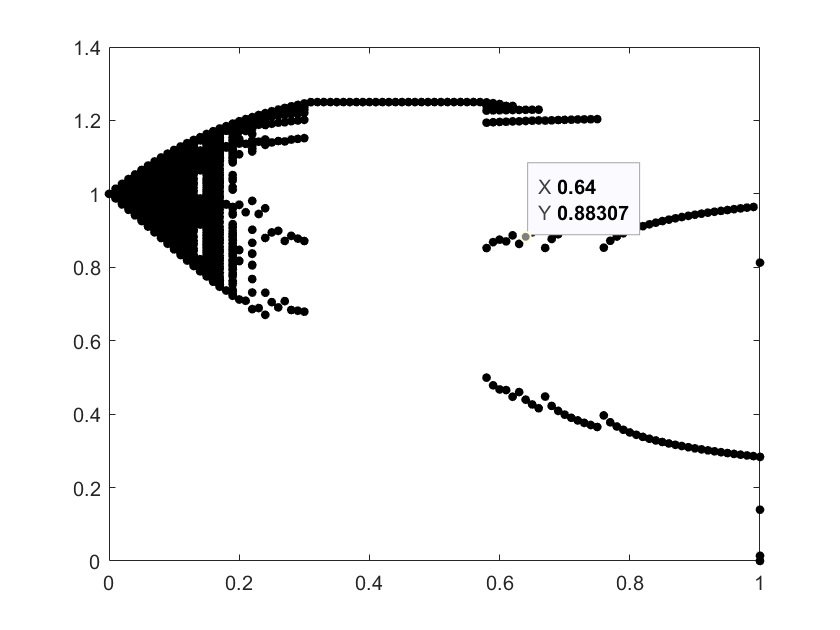

hold off

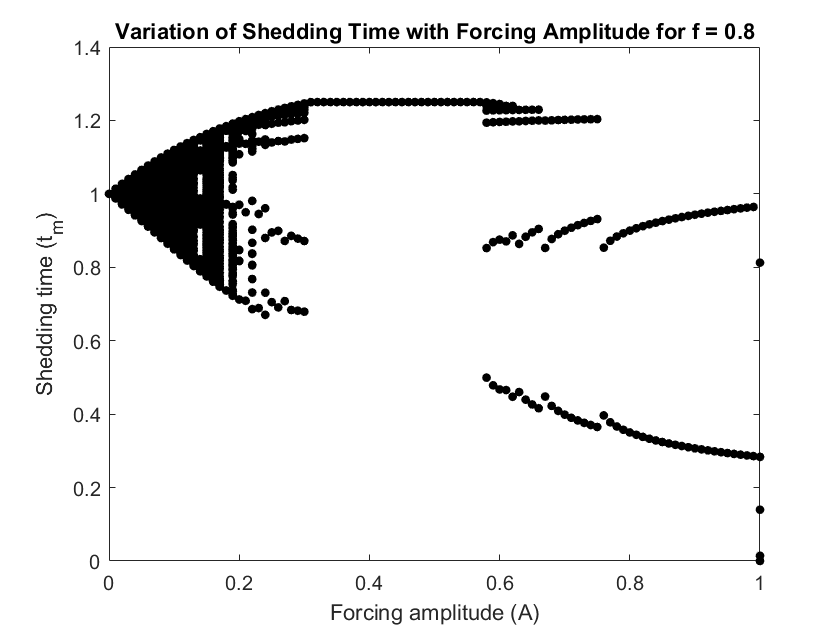

xlabel("Forcing amplitude (A)")
ylabel("Shedding time (t_m)")
title("Variation of Shedding Time with Forcing Amplitude for f = 0.8")